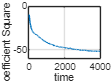

% P. A. C. Lopes, "A Bayesian Step Least Mean Squares Algorithm for Gaussian Signals"

% simulation parameters
NAvr=100;       % number of Monte Carlo runs
N=16;           % filter size
R=4000;         % simulation time
qv=0.01;        % measurement noise variance
qu=1;           % reference signal power
sw=1;           % optimal filter coefficient standard deviation
h = [1; 1/2];   % the reference spectral shaping filter

% algorithm parameters
alpha = 1/3;            % 1/(eigenvalues spread) should be always < 1 , related to equ.59
k = 2;                  % E[e^4]/E[e^2]^2 - 1

% simulate real filter
wo=(1.1*sinc((0:N-1)-10.7)-0.7*sinc((0:N-1)-13.2)+0.5*sinc((0:N-1)-5.3))';
wo=sw*wo/sqrt(sum(wo.^2));   % total energy = sw^2

% 預先建立用來儲存每一次模擬過程中重要變數
e_log=zeros(R,NAvr);  % 第NVar次的第R個時間點
d_log=zeros(R,NAvr);
A_log=zeros(R,2,2,NAvr);
b_log=zeros(R,2,NAvr);
qo_log=zeros(R,2,NAvr);
w_msq_log=zeros(R,NAvr);
mu_log=zeros(R,NAvr);
y_log = zeros(R, NAvr); 
s_log = zeros(R, NAvr);


for i=1:NAvr   % Monte Carlo 模擬
    rng(217928+i); % seed
    s = randn(1, R + length(h) - 1);
    u=sqrt(qu)*conv(s,h)/sqrt(sum(h.^2));  
    s = s(length(h):end); 
    s_log(:, i) = s(:);

    %% 先產生Gaussian white noise，再與濾波器h做convolution變colored noise並normalize
    u=u(length(h):end);     % 因為經過 conv()，所以把前面 padding 的濾波器延遲扣掉
    v=sqrt(qv)*randn(R,1);  % measurement noise N(0,qv)，randn() 會產生N(0,1)的白雜訊
    
    % initialization
    w=zeros(N,1); w(1)=1;  % 初始濾波器係數
    uv=zeros(N,1);  % tapped delay line u(n)、u(n-1)、⋯u(n-N+1)
    %     qo=ones(2,1);
    qo=[10 10]'; % [qw, qv]'
    A=zeros(2);  % 2x2 矩陣
    b=zeros(2,1);
    
    % simulation
    for n=1:R
        uv=[u(n) uv(1:N-1)']';  % 更新 LMS 的輸入向量
        d = uv'*wo + v(n);

        e = d - uv'*w;
        if n > N   % 剛開始的 uv 尚未填滿，略過前 N 點
            [w, qo, A, b, mu] = BSLMS(uv, d, w, qo, A, b, N, alpha, k);
            
            y_log(n, i) = uv' * w;
            
            %% statistics
            e_log(n,i) = e;
            d_log(n,i)= d;
            A_log(n,:,:,i)=A;
            b_log(n,:,i)=b;
            qo_log(n,:,i)=qo;
            w_msq_log(n,i)=mean((w-wo).^2);  % MSE
            mu_log(n,i)=mu;
        end        
    end
end


figure(1);
plot(10*log10(mean(w_msq_log,2)));
xlabel('time');
ylabel('Mean Coefficient Square Error (dBs)');
grid on;

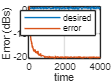


figure(2);
n_t_avr = 10;
desired_av = mean(abs(d_log).^2,2);
desired_av = mean(reshape(desired_av,n_t_avr,[]));
time=n_t_avr/2:n_t_avr:R;
plot(time, 10*log10(desired_av));
hold on;
error_av = mean(abs(e_log).^2,2);
error_av = mean(reshape(error_av,n_t_avr,[]));
plot(time, 10*log10(error_av));
hold off;
legend('desired', 'error');
xlabel('time');
ylabel('Error (dBs)');
grid on;

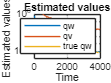


figure(3);
semilogy(mean(qo_log,3));  
hold on;
semilogy(mean(w_msq_log,2));  % MSE
hold off;
set(gca,'Ylim',[0.000001,1]);
legend('qw','qv', 'true qw');
ylabel('Estimated values');
xlabel('Time');
title('Estimated values')
grid on;

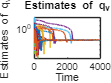


figure(4); 
semilogy(reshape(qo_log(:,2,:),R,[]));
ylabel('Estimates of q_v');
xlabel('Time');
title('Estimates of q_v')

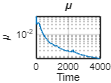


figure(5);
mu_plot = mean(mu_log, 2);
mu_plot(mu_plot <= 0) = NaN;
semilogy(mu_plot);
ylabel('\mu');
xlabel('Time');
title('\mu')
grid on;

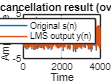


figure(7);
plot(s_log(:,1)); hold on;
plot(y_log(:,1));
legend('Original s(n)', 'LMS output y(n)');
xlabel('Time'); ylabel('Amplitude');
title('ISI cancellation result (overlay)');
grid on;

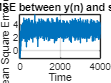


figure(8);
plot(10*log10(mean((y_log - s_log).^2, 2)));  % MSE over time
xlabel('Time');
ylabel('Mean Square Error (dB)');
title('MSE between y(n) and s(n)');
grid on;

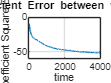


figure(9);
plot(10*log10(mean(w_msq_log, 2)));
xlabel('time');
ylabel('Mean Coefficient Square Error (dBs)');
title('Coefficient Error between w and w_o');
grid on;

function [w, qo, A, b, mu] = BSLMS(uv, d, w, qo, A, b, N, alpha, k)

    delta = 1e-9;   
    ddelta = 1e-99; % 加在除法分母裡防止出現 NaN 或 Inf
 
    e = d - uv'*w;  % error

    %% q measure update

    PT = uv'*uv + ddelta;
    P = PT/N;
    a = [PT, 1]';

    inv_zeta_sq_times_2 = 1/(2*(a'*qo)^2 + ddelta);

    A = A + inv_zeta_sq_times_2*(a*a');   %% equ29
    b = b + inv_zeta_sq_times_2*e^2*a;    %% equ30

    qo = (A+(ddelta+delta*trace(A))*eye(2)) \ b;

    xi = b'*qo;  % equ.26
    c = b/xi;    % equ.25
    nx = 4*xi/k;
    
    % equ.46
    z = qo(1)/(qo(1)*PT+qo(2));  
    if z < 0
        z = 0;
    end
    if z > 1/PT
        z = 1/PT;
    end
    

    %% Calculate mu=E[z]
    if nx <= 4 
        mu = z;
    else % Laplace Approximation 
        % first derivative
        d1 = ...
            -(nx*(pi*z*(A(1,1) - 2*PT*A(1,2)) + pi*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            2*pi*PT*(-1 + PT*z)*A(2,2)))/...
            (4.*(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + pi*power(-1 + PT*z,2)*A(2,2))) + ...
            ((-4 + nx)*(c(1) - PT*c(2)))/(2.*(z*c(1) + c(2) - PT*z*c(2)));

        % second derivative
        d2 = ...
            -((-4 + nx)*power(c(1) - PT*c(2),2)*power(z*c(1) + c(2) - PT*z*c(2),-2))/2. + ...
            (nx*power(pi*z*(A(1,1) - 2*PT*A(1,2)) + pi*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            2*pi*PT*(-1 + PT*z)*A(2,2),2)*power(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + ...
            pi*A(2,2)*power(-1 + PT*z,2),-2))/4. - ...
            (nx*(2*pi*(A(1,1) - 2*PT*A(1,2)) + 2*pi*A(2,2)*power(PT,2))*...
            power(pi*z*(z*A(1,1) - 2*(-1 + PT*z)*A(1,2)) + pi*A(2,2)*power(-1 + PT*z,2),-1))/4;

        
        if d2 >= 0
            mu = 1/(2*PT);  % at the middle of the interval
        else

            z0  = z - d1 / d2;   % z0 is approximately equal to z at the maximum
            pz = - d2;           % equ.66

            ax = sqrt(pz)*(1-z0*PT)/(sqrt(2)*PT);  % equ.67
            bx = z0*sqrt(pz)/sqrt(2);

            if ax+bx < 1e-9   % equ.68-71
                mu = 0; % lim a -> -b
            elseif abs(ax) > 10 && abs(bx) > 10  ...
                    && sign(ax)<0 && sign(bx)>0 % erfc saturates at 0
                mu = z0 + (-2+2*exp(-bx^2+ax^2))/...
                    (sqrt(2*pi*pz)*(...
                    -exp(-1/(2*ax^2))/(sqrt(pi)*ax)+...
                    -exp(-bx^2+ax^2-1/(2*bx^2))/(sqrt(pi)*bx)));
                % erfc(x) +-= exp(-x^2-1/(2x^2))/(sqrt(pi)*x)
            elseif abs(ax) > 10 && abs(bx) > 10  ...
                    && sign(ax)>0 && sign(bx)<0 % erfc saturates at 0
                mu = z0 + (-2*exp(bx^2-ax^2)+2)/...
                    (sqrt(2*pi*pz)*(...
                    -exp(bx^2-ax^2-1/(2*ax^2))/(sqrt(pi)*ax)+...
                    -exp(-1/(2*bx^2))/(sqrt(pi)*bx)));
                % erfc(x) +-= exp(-x^2-1/(2x^2))/(sqrt(pi)*x)
            elseif abs(ax) > 3 && abs(bx) > 3  ...
                    && sign(ax)*sign(bx) == -1 % erfs saturates at +1 and -1
                mu = z0 + (-2*exp(-ax^2)+2*exp(-bx^2))/...
                    (sqrt(2*pi*pz)*(...
                    -sign(ax)*erfc(abs(ax))+...
                    -sign(bx)*erfc(abs(bx))));
            else
                mu = z0 + (-2*exp(-ax^2)+2*exp(-bx^2))/...
                    (sqrt(2*pi*pz)*(erf(ax)+erf(bx)));
            end
           
        end
    end
    
    w = w + mu*uv*e;  % LMS central equ.


    gamma1 = 1;
    if qo(1) < 0
        gamma1 = -1;
    end
    gamma2 = 1;
    if qo(2) < 0
        gamma2 = -1;
    end
    
    %% Time Update
    C = [gamma1*(1-alpha*mu*P)^2, gamma2*alpha*mu^2*P;...
                         0,              gamma2]; % equ.59

    C1 = inv(C);  
    A = C1'*A*C1;  % equ.60
    b = C1'*b;     % equ.61

    %% Limit A , equ.62
    if trace(A) > 1e11  % assume max_trace(A) = 1e11
        kx = 1e11/trace(A);
        A = kx*A;
        b = kx*b;
    end
end